clc
clear all
g=9.81;
R=g/9;
thetad0=0;
theta0=1;
gamma=0.5;
ome=2;
[t,w]=pendulum4(R,theta0,thetad0,gamma,ome);
[t1,w1]=pendulum3(R,theta0,thetad0,gamma);
ind1= find(w(:,2).*circshift(w(:,2), [-1 0]) <= 0);
period1= 2*mean(diff(t(ind1(length(ind1)-10:length(ind1)-1))))

period1 = 3.1365

omega1=2*pi/period1

omega1 = 2.0033

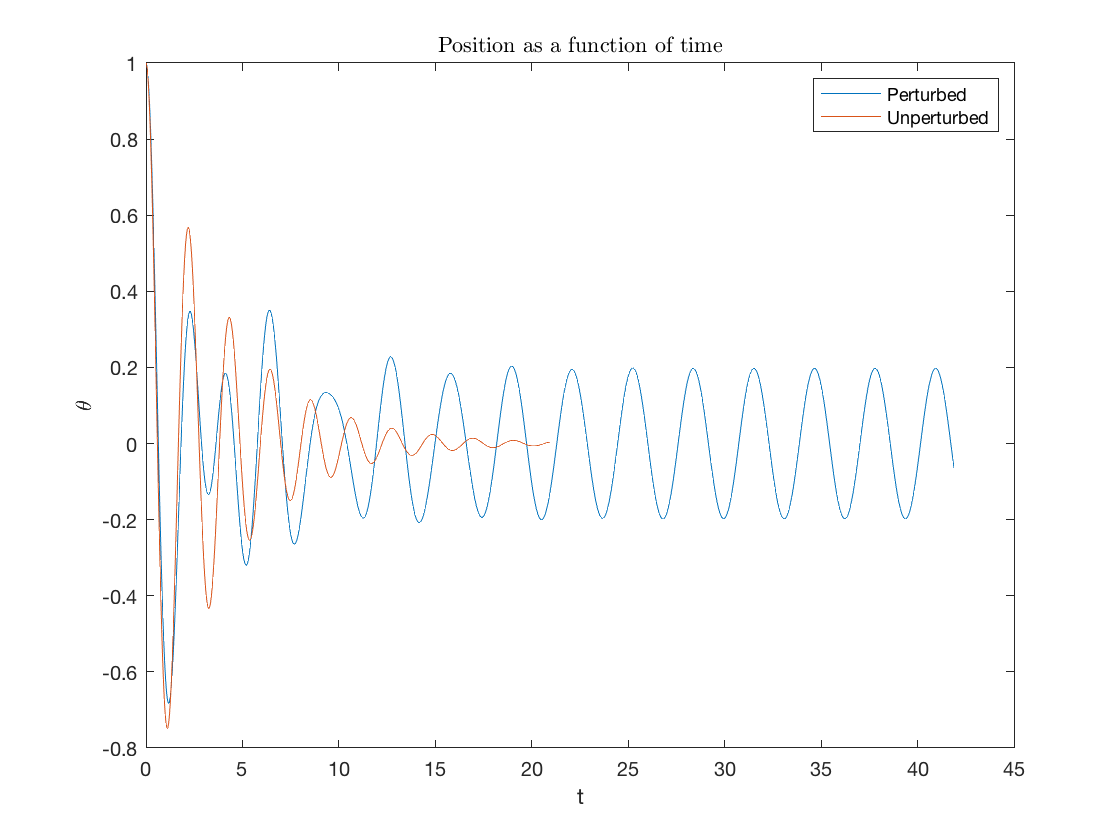

plot(t,w(:,1),t1,w1(:,1))
xlabel('t')
ylabel('\theta')
legend('Perturbed','Unperturbed')
title('Position as a function of time','interpreter','latex')

thetad0=1;
theta0=0;
ome=2;
[t,w]=pendulum4(R,theta0,thetad0,gamma,ome);
[t1,w1]=pendulum3(R,theta0,thetad0,gamma);
ind2= find(w(:,2).*circshift(w(:,2), [-1 0]) <= 0);
period2= 2*mean(diff(t(ind2(length(ind2)-10:length(ind2)-1))))

period2 = 3.1383

omega2=2*pi/period2

omega2 = 2.0021

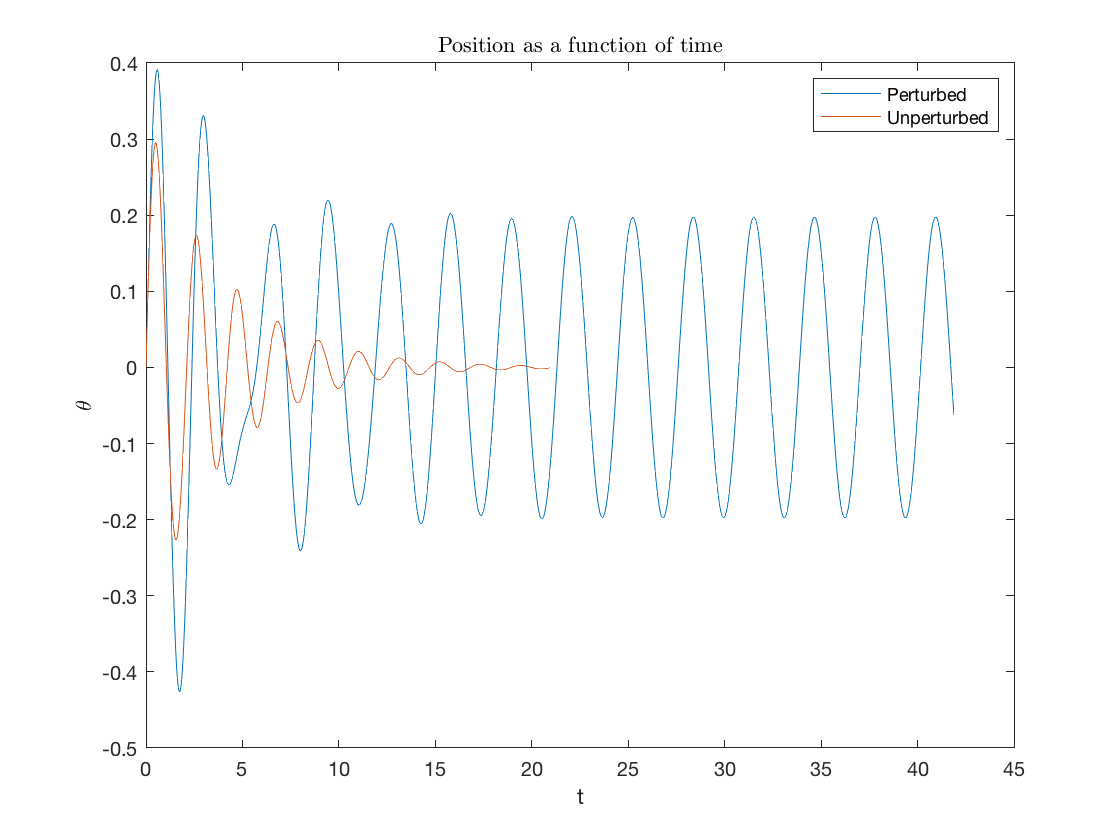

plot(t,w(:,1),t1,w1(:,1))
legend('Perturbed','Unperturbed')
xlabel('t')
ylabel('\theta')
title('Position as a function of time','interpreter','latex')

(a) with a drving force, the pendulum will undergo a steady state motion after a long time while it would decay and stop moving in unperturbed case. Even intial contitions are different, graph 1 and 2 showed us a similar final state. 

thetad0=0;
theta0=1;
ome=1;
[t,w]=pendulum4(R,theta0,thetad0,gamma,ome);
ind3= find(w(:,2).*circshift(w(:,2), [-1 0]) <= 0);
period3= 2*mean(diff(t(ind3(length(ind3)-10:length(ind3)-1))))

period3 = 6.2734

omega3=2*pi/period3

omega3 = 1.0016

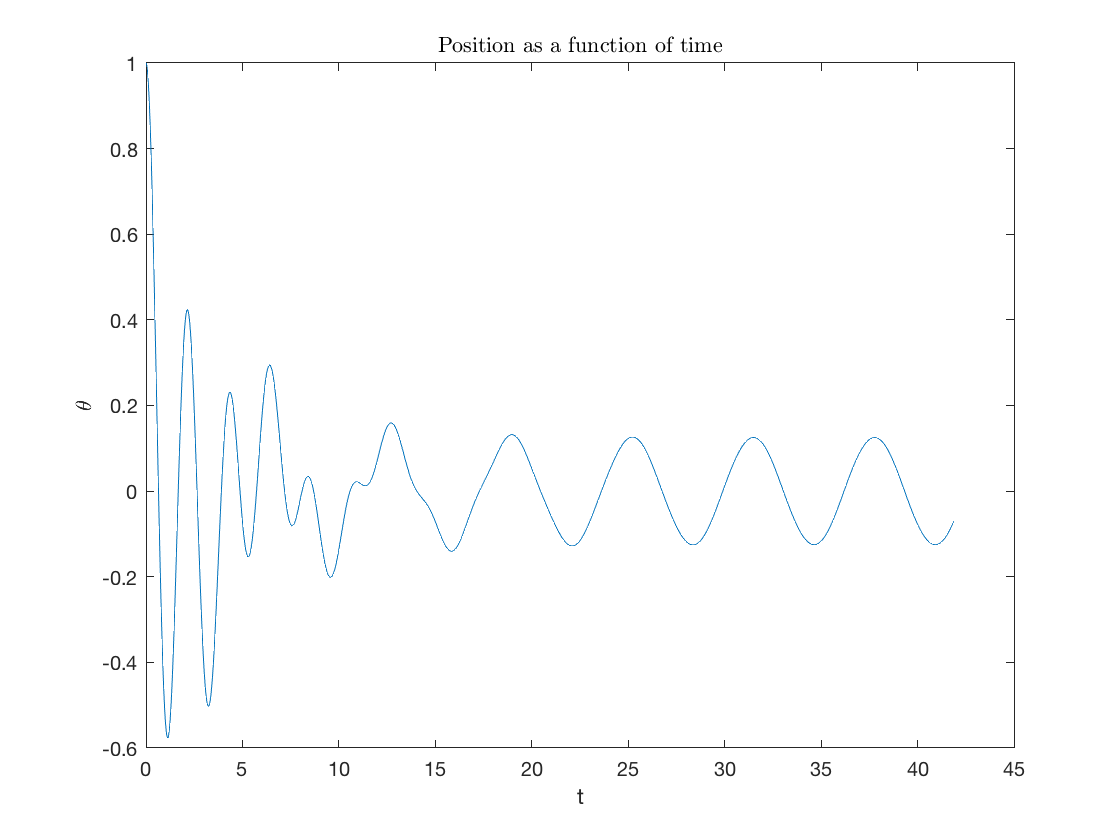

plot(t,w(:,1))
xlabel('t')
ylabel('\theta')
title('Position as a function of time','interpreter','latex')

(b) From graph 3,4 and 5, we can conclude that the frequency of the steady state motion dpends on the frequncy of the driving force.

thetad0=0;
theta0=1;
ome=4;
[t,w]=pendulum4(R,theta0,thetad0,gamma,ome);
ind4= find(w(:,2).*circshift(w(:,2), [-1 0]) <= 0);
period4= 2*mean(diff(t(ind4(length(ind4)-10:length(ind4)-1))))

period4 = 1.5718

omega4=2*pi/period4

omega4 = 3.9974

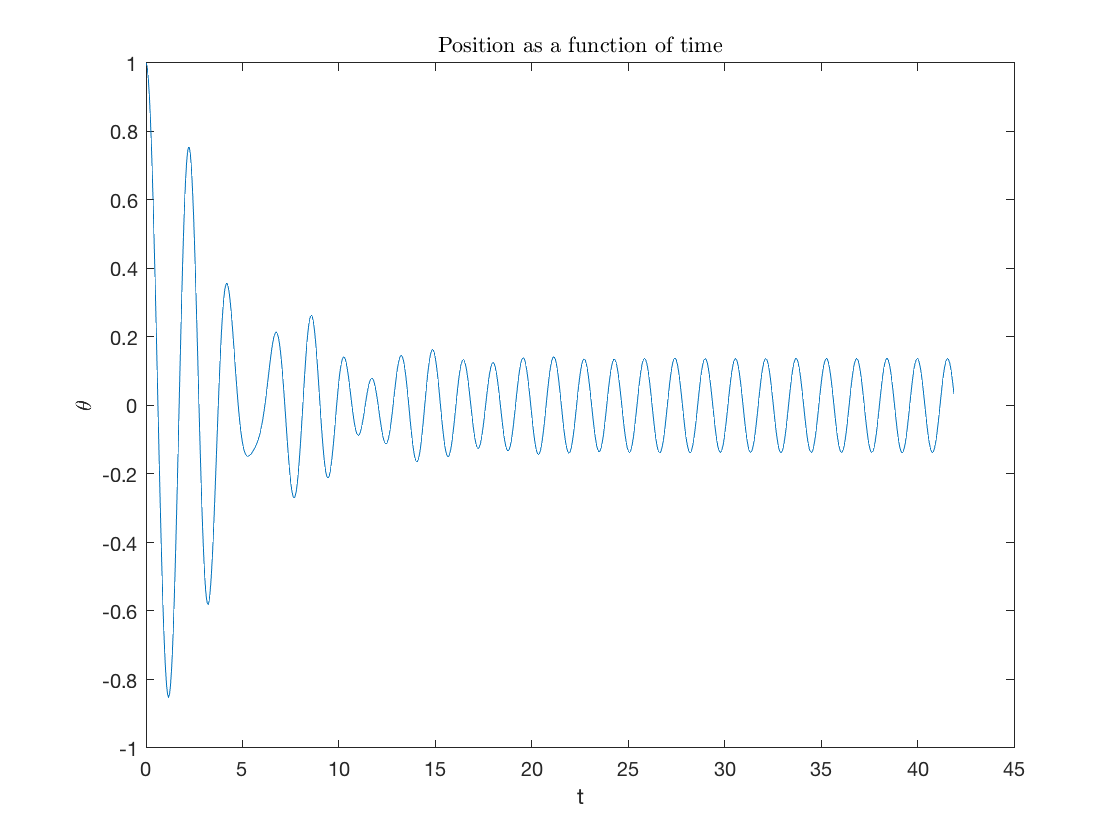

plot(t,w(:,1))
xlabel('t')
ylabel('\theta')
title('Position as a function of time','interpreter','latex')

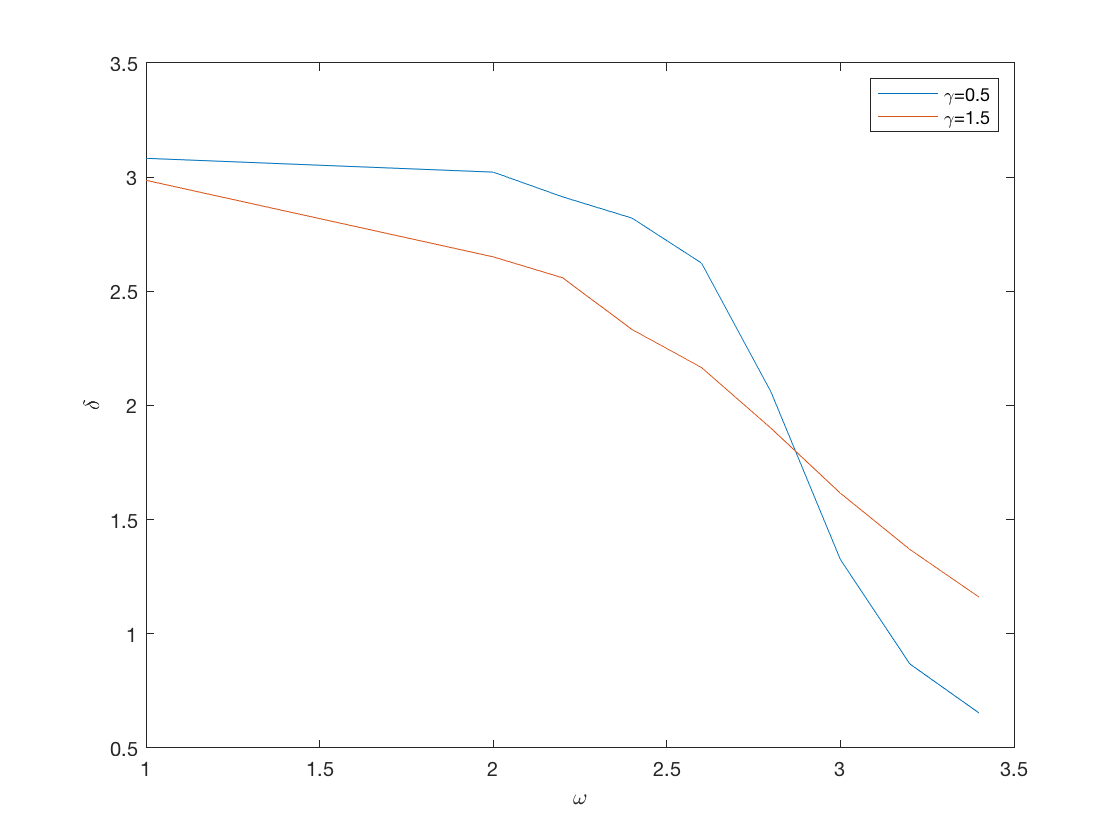

ome=[1,2,2.2,2.4,2.6,2.8,3.0,3.2,3.4];
gamma=[0.5,1.5];
thetad0=0;
theta0=1;
for i=1:length(ome)
    for j=1:length(gamma)
     [t,w]=pendulum4(R,theta0,thetad0,gamma(j),ome(i));
     ind5 = find(w(:,2)<=0 & circshift(w(:,2), [-1 0]) >=0);
     delta(i,j)=mean(mod(-ome(i)*t((ind5(length(ind5)-3:length(ind5)-1))),2*pi));
     ind5=zeros;
     end
end
plot(ome,delta(:,1),ome,delta(:,2))
legend('\gamma=0.5','\gamma=1.5')
xlabel('\omega')
ylabel('\delta')

(c)the phase difference would decrease with the frequency of drving force.